# **The emergence of hippocampal 4-Hz oscillations during wheel running**

Ivan Alisson Cavalcante Nunes de Lima and Hindiael Belchior

## **Abstract (250 words maximum) scope, novelty, and significance** 

Recent studies have shown oscillatory activity in the delta band frequency during running, but little is currently known about its underlying mechanisms.

Here we report the emergence of a 4-Hz oscillation in the CA1 LFP of rats running in a wheel that was essentially absent during running through a maze. The instantaneous 4-Hz amplitude and frequency positively correlated with running speed in the wheel but not in the maze. Hippocampal 4-Hz oscillations were resistant to pharmacological inactivation of the medial septum, while theta oscillations were abolished. These results dissociate the underlying mechanism of 4-Hz and theta oscillations in the hippocampus. 

Keywords: 4-Hz oscillations, hippocampus, medial septum inactivation, locomotion

## **HIGHLIGHTS**

- 4-Hz oscillations emerge in the rat hippocampus during wheel running

- Hippocampal 4-Hz amplitude and frequency correlate with running speed

- Hippocampal 4-Hz oscillations are resistant to medial septum inactivation 

## **IN BRIEF**

Lima and Belchior show that  4-Hz oscillations emerge in the rat hippocampus during stationary running on a wheel but not on the maze. 4-Hz oscillations are not dependent on septal inputs like theta oscillations.

## **GRAPHICAL ABSTRACT**

## **INTRODUCTION**

Locomotor activity modulates theta (6-10 Hz) oscillations in the rat hippocampus, which are strongly correlated by running speed. However, recent studies have shown that oscillatory activity in the delta (1-4 Hz) band is also associated with running speed in stationary conditions. 

While the former are modulated by running speed, the latter is maintained relatively constant. In our experiment, systematic changes in running speed resulted in consistent changes in 4-Hz power and frequency, following changes in interoceptive signals. Whether the major influences over hippocampal delta oscillations are due to self-motion cues or other physiological responses to running exercise remains to be further investigated.

Stationary running is fundamentally different from translational locomotion in the environment because it decouples afferent inputs derived from the body's internally and externally generated signals (Terrazas and McNaughton, 2005). While changes in proprioceptive signals follow changes in the internal metabolism, exteroceptive sensory signals (e.g., olfactive and visual landmarks) from the environment are maintained relatively constant. The respiratory rhythms, for instance, may shift from stimulus-induced sniffing activity to predominantly periodic breathing when rats abandon translational locomotion to engage in stationary running (ref). Changes in respiratory rhythms have been recently correlated with changes in hippocampal oscillation within the 1-10 Hz frequency range (Tort., 2018). We thus hypothesize that the rising of hippocampal delta oscillations during stationary runs may be related to respiratory signals that are concomitantly entrained by running activity. Future studies that simultaneously monitor breathing and hippocampal activity during stationary runs will be necessary to test this hypothesis. 

## **METHODS**

The dataset used in this study was previously acquired at the Pastalkova Lab on the Janelia Research Campus (Wang et al., 2014) and made available at [http://datadryad.org/](http://datadryad.org/) under public domain dedication license. 

### **Behavioral and electrophysiological recordings**

Two 64-channel linear silicon probes (Neuronexus or Janelia RC) were bilaterally implanted at the dorsal CA1 area (coordinates: -4.0 mm AP, ± 3 mm ML) of the rat hippocampus (n = 3 animals across ten sessions). Local field potentials, spiking activity, and digital video recordings were obtained during a delayed spatial alternation memory task in a U-shaped maze coupled to a wheel in which animals ran (~15 s) during the intertrial intervals. Electrophysiological and behavioral recordings were obtained before (n = 304 trials) and after (n = 501 trials) muscimol microinjections into the medial septum. Detailed experimental procedures can be found in previous publications (Wang et al., 2014).

### **Data analysis**

All data analyses were custom made and built-in routines in MATLAB. We excluded trials in which electrophysiological data presented electrical or movement artifacts of our analysis. Recordings were notch-filtered between 55 Hz and 65 Hz to remove 60 Hz electrical noise. LFP signals larger than two times the standard deviation were removed from three sessions of one animal (rat 943) due to movement artifacts. 

We then used the **“eegfilt”** function (EEGLAB Toolbox, [Delorme and Makeig, 2004)](https://www.zotero.org/google-docs/?PeKQqH) to obtain delta (3-5 Hz) and theta (6-10 Hz) components of the LFP signals. The **“pwelch”** function from the Signal Processing Toolbox to obtain the power spectral density (PSD). The **“hilbert”** function from the Signal Processing Toolbox to obtain the instantaneous delta and theta band amplitude, phase, and posteriorly, instantaneous frequency. The **“xcorr”** function (0.5-s window length, option type “coeff”) from the Signal Processing Toolbox. We used the **“spectrogram”** function (2-s window length with 90% overlap) from the Signal Processing Toolbox to obtain the time-frequency decomposition. The **“corr”** function (option type “Spearman”) from the Signal Processing Toolbox to obtain the correlation coefficients between running speed and the instantaneous amplitude and frequency at the delta and theta bands (5-s time windows). We used the **Shapiro-Wilk** test to evaluate data normality. **Wilcoxon rank-sum test** to compare between maze and wheel running conditions, and between wheel running previous to correct and incorrect choices and **Wilcoxon signed-rank **test was used to compare between wheel running pre and post muscimol injections. 

% A - Load scripts and project folder

clear
clc
close all
format compact
cd('D:/Ivan/OneDrive/Projetos/Códigos ( Profissional )/Material criado/ICE/Proj_BSc_Hippocampus_Delta_Analysis');
addpath('Routines/Functions/');
srate=1250;
dt=1/srate;

% B - Pre process
% Load database, select desired attributes, filter noise, calculate pwelch,
% eeg and hilbert
% Track: eeg, speed_MMsec, lapID
% Laps: WhlSpeedCCW, WhlSpeedCW
% Spike: cluu, res
% Clu: isIntern
% 
% 1 - Load and filter files

% Files source path
dbPathOne = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part1~/';
dbPathTwo = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part2~/';

% List of paths
filePaths = [dbPathOne; dbPathTwo];

% Pwelch - Specifications
WindowLength = 1*srate;
Overlap      = 0.9*srate;
NFFT         = 2^13;

% order = [0; 1];
tittles = "All_Combined";
wSpeed = 100;
mSpeed = 100;

savePath = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/Processed/Single Files/';

% Change to 1 if yout want to process all files and create the data ( 1st
% time )
processFiles = 0;
% Load files
if processFiles
    for i=1:size(filePaths,1)
        % List all files in each directory
        absolutFilePath = ls(fullfile(filePaths(i,1:end), '*.mat'));
        % Get the number of files
        [numFil, ~ ] = size(absolutFilePath);

        % Load each .mat in the structure
        for j=1:numFil
            dataSingle = load(strcat(filePaths(i,1:end),absolutFilePath(j, 1:end)), 'Track', 'Laps', 'Clu', 'Spike');

            % Select desired attributes
            trackNames = fieldnames(dataSingle.Track);
            trackNames(find(strcmp(trackNames, 'eeg'))) = [];
            trackNames(find(strcmp(trackNames, 'speed_MMsec'))) = [];
            trackNames(find(strcmp(trackNames, 'lapID'))) = [];
            trackNames(find(strcmp(trackNames, 'corrChoice'))) = [];
            lapsNames = fieldnames(dataSingle.Laps);
            lapsNames(find(strcmp(lapsNames, 'WhlSpeedCW'))) = [];
            lapsNames(find(strcmp(lapsNames, 'NLapCW'))) = [];
            spikeNames = fieldnames(dataSingle.Spike);
            spikeNames(find(strcmp(spikeNames, 'totclu'))) = [];
            spikeNames(find(strcmp(spikeNames, 'speed_MMsec'))) = [];
            spikeNames(find(strcmp(spikeNames, 'whlSpeed'))) = [];
            spikeNames(find(strcmp(spikeNames, 'res'))) = [];
            cluNames = fieldnames(dataSingle.Clu);
            cluNames(find(strcmp(cluNames, 'isIntern'))) = [];
            
            dataSingle.Track = rmfield(dataSingle.Track,trackNames);
            dataSingle.Laps = rmfield(dataSingle.Laps,lapsNames);        
            dataSingle.Spike = rmfield(dataSingle.Spike,spikeNames);  
            dataSingle.Clu = rmfield(dataSingle.Clu,cluNames);  
            dataSingle.Name = absolutFilePath(j, 1:16);

            % Save unmodified LFP
            dataSingle.Track.origEeg = dataSingle.Track.eeg;
            % Filter noise
            dataSingle = filterLFP(dataSingle, srate);
            
            % Process ( Pwelch, hilbert, eeg )
            dataSingle = fillStruct(srate, WindowLength, Overlap, NFFT, dataSingle, wSpeed, mSpeed);

            Spike = dataSingle.Spike;
            Name = dataSingle.Name;
            Clu = dataSingle.Clu;  
            Lfp = dataSingle.Lfp;
            Delta = dataSingle.Delta;
            Theta = dataSingle.Theta;
            Choice = dataSingle.Choice;
            Speed = dataSingle.Speed;
            Pwelch = dataSingle.Pwelch;
            % Save
            mmtTtl = 'Pre';
            if i == 2
                mmtTtl = 'Pos';
            end

            file = sprintf('%s%s/%s/%s.mat', savePath, tittles, mmtTtl, Name);
            save(file, 'Clu', 'Spike', 'Name', 'Pwelch', 'Lfp', 'Delta', 'Theta', ...
               'Choice', 'Speed', '-v7.3')  

            sprintf('Dir: %d, File: %d', i, j)
        end
    end
end
clearvars -except srate dt Band Clu Name Spike

% C - Load processed file ( if the data was previously created, start here to continue analysis )
% 1 - Load files. Filtered data, with pwelch and eegfilt
tic
clear
clc
close all
format compact
cd('D:/Ivan/OneDrive/Projetos/Códigos ( Profissional )/Material criado/ICE/Proj_BSc_Hippocampus_Delta_Analysis');
addpath('Routines/Functions/');
srate=1250;
dt=1/srate;

rootPath = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/Processed/Single Files/';
subPath = ["All_Combined"];
idx = 1;
loadPath = sprintf('%s%s/', rootPath, subPath(idx));

% Load files
dataFull = {};
% Load Pre
absolutFilePath = ls(fullfile(sprintf('%sPre/', loadPath), '*.mat'));
for file=1:size(absolutFilePath, 1)
    fileName = absolutFilePath(file, :);
    dataFull{1, file} = load(strcat(loadPath, 'Pre\', fileName));
%     sprintf('%s - Pre - File: %d', subPath(idx), file)
end
% Load Pos
absolutFilePath = ls(fullfile(sprintf('%sPos/', loadPath), '*.mat'));
for file=1:size(absolutFilePath, 1)
    fileName = absolutFilePath(file, :);
    dataFull{2, file} = load(strcat(loadPath, 'Pos\', fileName));
%     sprintf('%s - Pos - File: %d', subPath(idx), file)
end
[numReads, numSubReads ] = size(dataFull);
clearvars -except dataFull srate dt numReads numSubReads 
toc

Elapsed time is 61.442183 seconds.


## **RESULTS **

### **4-Hz oscillations emerge in the rat hippocampus during wheel running**

Rats were trained to perform a delayed spatial alternation task on a U-shaped maze and run for 15 s on a wheel during the inter-trial intervals (Figure 1A). Local field potential (LFP) and spiking activity were recorded from the CA1 area of the dorsal hippocampus of three rats (805 trials across 10 sessions). Consistent with previous reports, spectral decomposition of CA1 LFP showed prominent theta (6-10 Hz) oscillations while rats ran throughout the maze and on the wheel (Figure 1B, left and right, respectively). Interestingly, however, only running on the wheel further exhibited remarkable rhythmicity at a slower frequency around 4 Hz. Hippocampal 4-Hz oscillations were noticeable at the raw LFP signals and spectrograms during wheel running but not at maze runs in trials with similar running speeds (Figure 1B and Supplementary Figure X). Autocorrelograms revealed strong rhythmicity during maze and wheel running with interpeak intervals of 145 ms (6.8 Hz) and 320 ms (3.1 Hz), respectively (Figure 1C). Averaged power spectra at the group level show a single peak at 8.7 Hz during maze running and two peaks at 7.8 Hz and at 4 Hz at the wheel (Figure 1D). 4-Hz band power was significantly higher during wheel runs than at maze runs (Figure 1E, left, p < 0.01, Wilcoxon signed-rank test). Theta peak power was also higher at the wheel (Figure 1E, right, p < 0.01, Wilcoxon signed-rank test), while theta peak frequency was significantly slower at the wheel than at the maze (Supplementary Figure X, p<0.01, Wilcoxon signed-rank test).

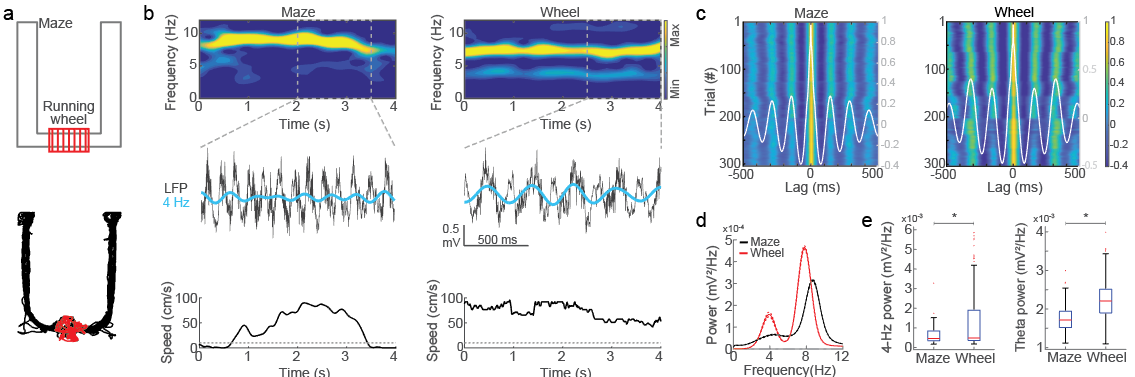

**Figure 1 - Hippocampal 4-Hz oscillations emerge during wheel running, but not maze running. (A) **Schematic representation of the U-shaped maze (gray) coupled to a running wheel (red, upper). A typical example of the spatial trajectory of a rat on the maze (black) and on the wheel (red, lower).** (B) **Spectrograms showing energy at 0-12 Hz frequencies during representative maze and wheel runs (left and right, respectively, upper). Notice that only the wheel running exhibits prominent energy at 4 Hz and 8 Hz frequencies. Raw LFP and 3-5 Hz band-filtered signals (gray and cyan, respectively, middle), and the instantaneous running speed at the same maze and wheel runs as above (lower). (**C)** Autocorrelograms of LFP signals across 304 runs at the maze and the wheel (left and right, respectively). Gray traces represent the average autocorrelograms across trials. Interpeak intervals were 145 ms (6.8 Hz) during maze runs and 320 ms (3.1 Hz) during wheel runs. (**D) **Average power spectra from LFP obtained during maze and wheel runs (black and red, respectively, n=304 trials). Solid lines depict mean and dashed lines depict ± SEM. (**E)** Boxplot showing the distribution of power at the 3-5 Hz band during maze and wheel runs (left, p < 0.01, Wilcoxon signed-rank test). Distribution of power at the theta (6-10 Hz) band during maze and wheel runs (right, p < 0.01, Wilcoxon signed-rank test).

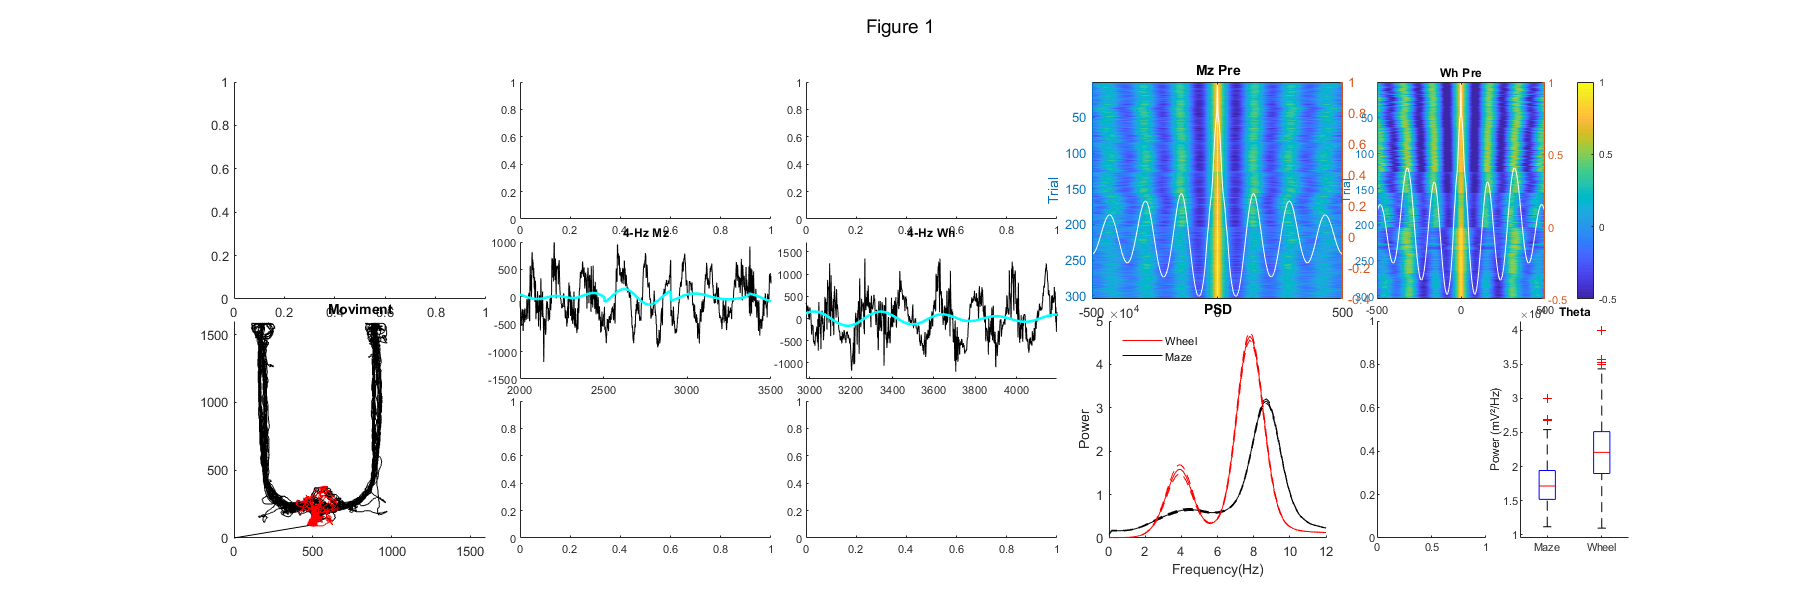

% Panel A
fig = figure(1);clf
fig.Position = [0,0, 1800, 600];
sgtitle('Figure 1')
% a1
subplot(6,10,[1,2,11,12,21,22])

% a2
subplot(6,10,[31,32,41,42,51,52])
% Load file
if ~exist('tempXY')
   tic
   tempXY = load('D:\Ivan\Downloads\ProjetoWheelMaze\Dataset\dryad\Wang_et_al_eLife2016_data_part1~\A498-20120815-01_BehavElectrDataLFP.mat');
   toc
end
lap    = tempXY.Laps.NLapCW + tempXY.Laps.NLapCCW;
xcoord = tempXY.Track.xMM;
ycoord = tempXY.Track.yMM;
plot(ycoord(20000:end),xcoord(20000:end),'k-')

tempX = [];
tempY = [];
for l=1:max(tempXY.Laps.lapID)
   lapidx = lap == l;
   tempX = [tempX; xcoord(lapidx)];
   tempY = [tempY; ycoord(lapidx)];
end

hold on
plot(tempY,tempX,'r-')
xlim([0 1600])
ylim([0 1600])
box off
title('Moviment')
hold off

% Panel B
tempData = dataFull{1,1};
% b1.1 Imagesc
subplot(6,10,[3,4,13,14])
% b1.2 LFP
subplot(6,10,[23,24,33,34])
mzSpeed = tempData.Speed.Mz{1} > 100;
plot(tempData.Lfp{1}(mzSpeed), 'k')
xlim([2000,3500])
hold on
plot(tempData.Delta.Band{1}(mzSpeed), 'c', 'LineWidth', 2)
box off
hold off
title('4-Hz Mz')

% b1.3 Speed
subplot(6,10,[43,44,53,54])
% b2.1 Imagesc
subplot(6,10,[5,6,15,16])
% b2.2 LFP
subplot(6,10,[25,26,35,36])
whSpeed = tempData.Speed.Wh{1} > 100;
plot(tempData.Lfp{1}(whSpeed), 'k')
xlim([3000,4000])
hold on
plot(tempData.Delta.Band{1}(whSpeed), 'c', 'LineWidth', 2)
hold off
box off
title('4-Hz Wh')
% b2.3 Speed
subplot(6,10,[45,46,55,56])

% Panel C
% Pre = 1, Post = 2
nData = 1;

auxMzAcgCombine = [];
auxWhAcgCombine = [];
for i=1:numSubReads
    dataTemp = dataFull{nData, i};
    
    laps = size(dataTemp.Choice, 1);
    for lp=1:laps

        mzMask = dataTemp.Speed.Mz{lp} > 100;
        whMask = dataTemp.Speed.Wh{lp} > 100;

        LFPMz = dataTemp.Lfp{lp}(mzMask);
        LFPWh = dataTemp.Lfp{lp}(whMask);

        % Capture snippet
        [acgMz, lagsMz] = xcorr(LFPMz,'coef', 500);    
        [acgWh, lagsWh] = xcorr(LFPWh,'coef', 500);    

        auxMzAcgCombine = [auxMzAcgCombine, acgMz];
        auxWhAcgCombine = [auxWhAcgCombine, acgWh];
    end
end
% c1
subplot(6,10,[7,8,17,18,27,28])
yyaxis left
plotImagesc(grIdx(nData, 1), lagsMz, auxMzAcgCombine', 'Mz', 'Pre')
hold on
val = size(auxMzAcgCombine, 1)/2;
xLimValue = -val:val-1;
yyaxis right
plot(xLimValue, mean(auxMzAcgCombine, 2), 'w')
hold off

% c2
subplot(6,10,[9,10,19,20,29,30])
yyaxis left
plotImagesc(grIdx(nData, 2), lagsWh, auxWhAcgCombine', 'Wh', 'Pre')
colorbar()
caxis([-0.5, 1])
yyaxis right
plot(xLimValue, mean(auxWhAcgCombine, 2), 'w')
hold off

% Panel D
subplot(6,10,[37,38,47,48,57,58])
nTrials = 0;
data = {struct('Mz', [], 'Wh', []), struct('Mz', [], 'Wh', [])}; 
for i=1:numSubReads
    nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

    dataTemp = dataFull{nData, i}.Pwelch;

    data{nData}.Mz = [data{nData}.Mz; dataTemp.Psd.Mz];
    data{nData}.Wh = [data{nData}.Wh; dataTemp.Psd.Wh];
end

x = dataTemp.Frequency;
meanWh = mean(data{nData}.Wh);
meanMz = mean(data{nData}.Mz);
% Std  
stdWh = std(data{nData}.Wh)/sqrt(nTrials); 
stdMz = std(data{nData}.Mz)/sqrt(nTrials);

plot(x, meanWh, 'r', x, meanMz, 'k')
hold on
plot(x, meanMz+stdMz, 'k--', x, meanMz-stdMz, 'k--')
plot(x, meanWh+stdWh, 'r--', x, meanWh-stdWh, 'r--')
hold off
xlim([0,12])
ylim([0 , 50000])
label1{1} = 'Wheel';
label1{2} = 'Maze';
box off
legend(label1,'location','Northwest','orientation','vertical')
legend('boxoff')
ylabel('Power')
xlabel('Frequency(Hz)')
axis square
title('PSD')

% Panel E
bands = [3,5; 6,10];
% e1
data = {struct('Mz', [], 'Wh', [], 'Freq', []), struct('Mz', [], 'Wh', [], 'Freq', [])}; 

nTrials = 0;
bnd = 1;
for i=1:numSubReads
    dataTemp = dataFull{nData, i}.Pwelch;
    nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

    fMask = ( dataTemp.Frequency  > bands(bnd,1) ) & ( dataTemp.Frequency  < bands(bnd,2));

    data{nData}.Mz = [data{nData}.Mz; dataTemp.Psd.Mz(:, fMask)];
    data{nData}.Wh = [data{nData}.Wh; dataTemp.Psd.Wh(:, fMask)];
end

meanMz = mean(data{nData}.Mz,2);
meanWh = mean(data{nData}.Wh,2);

subplot(6,10,[39,49,59])
% boxplot([meanMz, meanWh])
% box off
% xticklabels(["Maze", "Wheel"])
% ylabel('Power (mV²/Hz)')
% e2
% title('4-Hz')

subplot(6,10,[40,50,60])
data = {struct('Mz', [], 'Wh', [], 'Freq', []), struct('Mz', [], 'Wh', [], 'Freq', [])}; 

nTrials = 0;
bnd = 2;
for i=1:numSubReads
    dataTemp = dataFull{nData, i}.Pwelch;
    nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

    fMask = ( dataTemp.Frequency  > bands(bnd,1) ) & ( dataTemp.Frequency  < bands(bnd,2));

    data{nData}.Mz = [data{nData}.Mz; dataTemp.Psd.Mz(:, fMask)];
    data{nData}.Wh = [data{nData}.Wh; dataTemp.Psd.Wh(:, fMask)];
end

meanMz = mean(data{nData}.Mz,2);
meanWh = mean(data{nData}.Wh,2);

boxplot([meanMz, meanWh])
box off
xticklabels(["Maze", "Wheel"])
ylabel('Power (mV²/Hz)')
title('Theta')

### **Hippocampal 4-Hz amplitude correlates with running speed**

We next investigated whether hippocampal 4-Hz oscillations are associated with running speed. First, we observed that animals ran faster at the wheel than maze (Figure 2A, red and black, respectively, p < 0.01, Wilcoxon signed-rank test, n = 304 trials), which could suggest that higher running speed underlies the rising of 4-Hz during wheel runs. However, scatter plots show that the instantaneous running speed and the 4-Hz amplitude correlated positively at the wheel and negatively at the maze (Figure 2B, left, r = 0.38 and r = -0.14, respectively, Spearman’s correlation test), indicating that the emergence of 4-Hz oscillations on the wheel can not be only explained by running speed but correlated specifically with running speed on the wheel. In turn, the amplitude of theta oscillations positively correlated with running speed during maze and wheel runs (Figure 2B, right, r = 0.14, and r = 0.01, respectively, Spearman’s correlation test). The instantaneous 4-Hz peak frequency exhibited a positive relationship with running speed during both wheel and maze runs (Figure 2C, left, r = 0.34, and r = 0.27, respectively, Spearman’s correlation test). Similarly, theta peak frequency and running speed were positively correlated at the maze and at the wheel (Figure 2C, right, r = 0.43, and r = 0.24, respectively, Spearman’s correlation test). 

We then evaluated 4-Hz and theta oscillations during wheel runs according to choice performance at the spatial alternation memory task. Figure 2D shows the power spectra at 0-12 Hz obtained from wheel runs previous to correct and incorrect choices. We found that neither 4-Hz nor theta band power was statistically different during wheel runs previous to correct and incorrect choices (Figure 2E, p = 0.257 and p = 0.338, respectively, Wilcoxon rank-sum test). Similarly, neither the 4-Hz nor theta peak frequency was significantly different during wheel runs before correct and incorrect trials (Figure 2F, p = 0.754 and p = 0.36, respectively, Wilcoxon rank-sum test). 

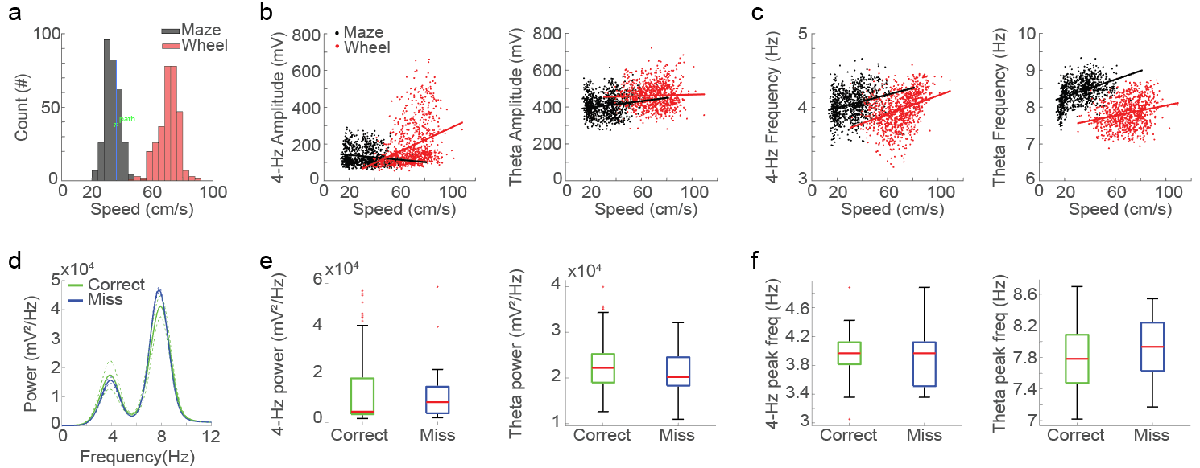

**Figure 2 - Hippocampal 4-Hz oscillations are modulated by running speed but are not affected by memory performance**. **(A)** Histograms of running speeds at the maze (black) and at the wheel (red). **(B)** Scatter plots of running speed and the instantaneous 4-Hz amplitude (left) and theta amplitude (right). **(C)** Scatter plots show the relationship between running speed and the instantaneous 4-Hz frequency (left) and theta frequency (right). **(D)** Average power spectra during wheel run previous to correct (green, n=286 trials) and incorrect (blue, n=18 trials) choices at the spatial alternation memory task. Solid lines represent means and dashed lines represent ± SEM. **(E)** Boxplots of 4-Hz band power (left) and theta band power (right) during wheel runs previous to correct and incorrect choices. **(F)** Boxplots of 4-Hz peak frequency (left) and theta peak frequency (right) during wheel runs before correct and incorrect trials. Supplementary figure XX shows the distribution 4-Hz and theta band power and peak frequency.

% Figura 2
speedthresh=100;
oneStep = struct("Mz", [], "Wh", []);
secStep = struct('Trial', oneStep, 'Full', oneStep);
nData = 1;
respDt = struct('Amp', secStep, 'Fre', secStep);
respTh = struct('Amp', secStep, 'Fre', secStep);
speed = secStep;

for file=1:numSubReads
    dataTemp = dataFull{nData, file};
    
    for session=1:length(dataTemp.Choice)
        % Speed
        speedMzMask = dataTemp.Speed.Mz{session} > speedthresh;
        speedWhMask = dataTemp.Speed.Wh{session} > speedthresh;
        
        speed.Trial.Mz = [ speed.Trial.Mz, mean(dataTemp.Speed.Mz{session}(speedMzMask)) ];
        speed.Trial.Wh = [ speed.Trial.Wh, mean(dataTemp.Speed.Wh{session}(speedWhMask)) ];
        speed.Full.Mz = [ speed.Full.Mz; dataTemp.Speed.Mz{session}(speedMzMask) ];
        speed.Full.Wh = [ speed.Full.Wh; dataTemp.Speed.Wh{session}(speedWhMask) ];
        % Amplitude
        respDt.Amp.Trial.Mz = [respDt.Amp.Trial.Mz, mean(dataTemp.Delta.Amplitude{session}(speedMzMask)) ];
        respDt.Amp.Trial.Wh = [respDt.Amp.Trial.Wh, mean(dataTemp.Delta.Amplitude{session}(speedWhMask)) ];
        respTh.Amp.Trial.Mz = [respTh.Amp.Trial.Mz, mean(dataTemp.Theta.Amplitude{session}(speedMzMask)) ];
        respTh.Amp.Trial.Wh = [respTh.Amp.Trial.Wh, mean(dataTemp.Theta.Amplitude{session}(speedWhMask)) ];
        respDt.Amp.Full.Mz = [respDt.Amp.Full.Mz; dataTemp.Delta.Amplitude{session}(speedMzMask)' ];
        respDt.Amp.Full.Wh = [respDt.Amp.Full.Wh; dataTemp.Delta.Amplitude{session}(speedWhMask)' ];
        respTh.Amp.Full.Mz = [respTh.Amp.Full.Mz; dataTemp.Theta.Amplitude{session}(speedMzMask)' ];
        respTh.Amp.Full.Wh = [respTh.Amp.Full.Wh; dataTemp.Theta.Amplitude{session}(speedWhMask)' ];
        % Frequency
        respDt.Fre.Trial.Mz = [respDt.Fre.Trial.Mz, mean(dataTemp.Delta.InstFreq{session}(speedMzMask)) ];
        respDt.Fre.Trial.Wh = [respDt.Fre.Trial.Wh, mean(dataTemp.Delta.InstFreq{session}(speedWhMask)) ];
        respTh.Fre.Trial.Mz = [respTh.Fre.Trial.Mz, mean(dataTemp.Theta.InstFreq{session}(speedMzMask)) ];
        respTh.Fre.Trial.Wh = [respTh.Fre.Trial.Wh, mean(dataTemp.Theta.InstFreq{session}(speedWhMask)) ];
        respDt.Fre.Full.Mz = [respDt.Fre.Full.Mz; dataTemp.Delta.InstFreq{session}(speedMzMask)' ];
        respDt.Fre.Full.Wh = [respDt.Fre.Full.Wh; dataTemp.Delta.InstFreq{session}(speedWhMask)' ];
        respTh.Fre.Full.Mz = [respTh.Fre.Full.Mz; dataTemp.Theta.InstFreq{session}(speedMzMask)' ];
        respTh.Fre.Full.Wh = [respTh.Fre.Full.Wh; dataTemp.Theta.InstFreq{session}(speedWhMask)' ];
        
    end
end

oneStep = struct("Mz", [], "Wh", []);
secondStep = struct('Dt', oneStep, 'Th', oneStep);
binsResp = struct('Speed', secondStep, 'Amp', secondStep,'Fre', secondStep);
thirdStep = struct('R_Amp', oneStep, 'P_Amp', oneStep, 'R_Fre', oneStep, 'P_Fre', oneStep);
rpBin = struct('Dt', thirdStep, 'Th', thirdStep);

t=5; %bin in sec
count=1;
for i=1:(t*srate):length(speed.Full.Mz)-(t*srate)
    try
        binsResp.Speed.Dt.Mz = [binsResp.Speed.Dt.Mz, mean(speed.Full.Mz(count:count+(t*srate))) ];
        binsResp.Amp.Dt.Mz = [binsResp.Amp.Dt.Mz, mean(respDt.Amp.Full.Mz(count:count+(t*srate))) ];
        binsResp.Fre.Dt.Mz = [binsResp.Fre.Dt.Mz, mean(respDt.Fre.Full.Mz(count:count+(t*srate))) ];

        binsResp.Speed.Th.Mz = [binsResp.Speed.Th.Mz, mean(speed.Full.Mz(count:count+(t*srate))) ];
        binsResp.Amp.Th.Mz = [binsResp.Amp.Th.Mz, mean(respTh.Amp.Full.Mz(count:count+(t*srate))) ];
        binsResp.Fre.Th.Mz = [binsResp.Fre.Th.Mz, mean(respTh.Fre.Full.Mz(count:count+(t*srate))) ];
        count=count+(t*srate);
    end
end
[rpBin.Dt.R_Amp.Mz, rpBin.Dt.P_Amp.Mz] = corr( binsResp.Speed.Dt.Mz', binsResp.Amp.Dt.Mz', 'Type', 'Spearman');
[rpBin.Dt.R_Fre.Mz, rpBin.Dt.P_Fre.Mz] = corr( binsResp.Speed.Dt.Mz', binsResp.Fre.Dt.Mz', 'Type', 'Spearman');
[rpBin.Th.R_Amp.Mz, rpBin.Th.P_Amp.Mz] = corr( binsResp.Speed.Th.Mz', binsResp.Amp.Th.Mz', 'Type', 'Spearman');
[rpBin.Th.R_Fre.Mz, rpBin.Th.P_Fre.Mz] = corr( binsResp.Speed.Th.Mz', binsResp.Fre.Th.Mz', 'Type', 'Spearman');

count=1;
for i=1:(t*srate):length(speed.Full.Wh)-(t*srate)
    try
        binsResp.Speed.Dt.Wh = [binsResp.Speed.Dt.Wh, mean(speed.Full.Wh(count:count+(t*srate))) ];
        binsResp.Amp.Dt.Wh = [binsResp.Amp.Dt.Wh, mean(respDt.Amp.Full.Wh(count:count+(t*srate))) ];
        binsResp.Fre.Dt.Wh = [binsResp.Fre.Dt.Wh, mean(respDt.Fre.Full.Wh(count:count+(t*srate))) ];

        binsResp.Speed.Th.Wh = [binsResp.Speed.Th.Wh, mean(speed.Full.Wh(count:count+(t*srate))) ];
        binsResp.Amp.Th.Wh = [binsResp.Amp.Th.Wh, mean(respTh.Amp.Full.Wh(count:count+(t*srate))) ];
        binsResp.Fre.Th.Wh = [binsResp.Fre.Th.Wh, mean(respTh.Fre.Full.Wh(count:count+(t*srate))) ];
        count=count+(t*srate);
    end
end
[rpBin.Dt.R_Amp.Wh, rpBin.Dt.P_Amp.Wh] = corr( binsResp.Speed.Dt.Wh', binsResp.Amp.Dt.Wh', 'Type', 'Spearman');
[rpBin.Dt.R_Fre.Wh, rpBin.Dt.P_Fre.Wh] = corr( binsResp.Speed.Dt.Wh', binsResp.Fre.Dt.Wh', 'Type', 'Spearman');
[rpBin.Th.R_Amp.Wh, rpBin.Th.P_Amp.Wh] = corr( binsResp.Speed.Th.Wh', binsResp.Amp.Th.Wh', 'Type', 'Spearman');
[rpBin.Th.R_Fre.Wh, rpBin.Th.P_Fre.Wh] = corr( binsResp.Speed.Th.Wh', binsResp.Fre.Th.Wh', 'Type', 'Spearman');

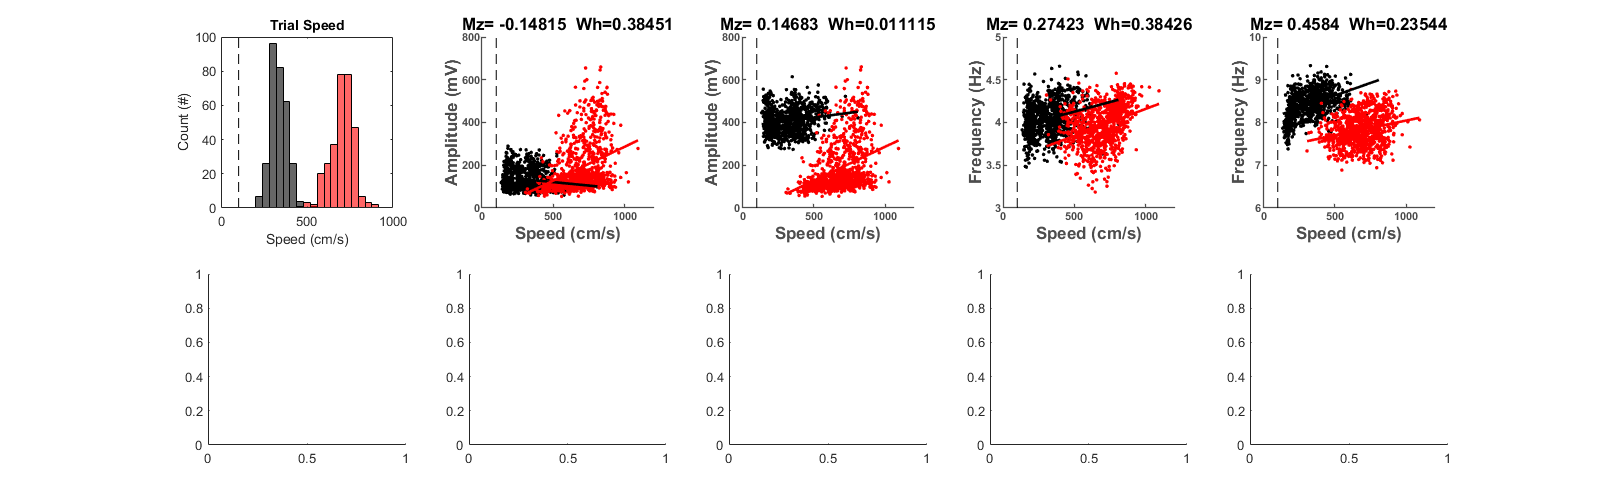


fig = figure(2);clf
fig.Position = [0,0, 1600, 500];
% Panel A
subplot(2,5,1)
title(sprintf('Delta x Theta - %s', key))

bins=[0:40:1000];
histogram(speed.Trial.Mz,bins,'FaceColor',[0 0 0])
hold on
histogram(speed.Trial.Wh,bins,'FaceColor',[1 0 0])
plot([speedthresh, speedthresh],[0 100],'k--')
xlim([0, 1000])
xlabel 'Speed (cm/s)'
ylabel 'Count (#)'
title('Trial Speed')
axis square
hold off
% Panel B
% b1
subplot(2,5,2)
plotFig2(2, binsResp.Speed.Dt.Mz, binsResp.Amp.Dt.Mz, binsResp.Speed.Dt.Wh, binsResp.Amp.Dt.Wh,  speedthresh, [0, 800], [0, 1200],...
        [0], ['Mz= ', num2str(rpBin.Dt.R_Amp.Mz), '  Wh=', num2str(rpBin.Dt.R_Amp.Wh)], 'Speed (cm/s)', 'Amplitude (mV)')

% b2
subplot(2,5,3)
% Speed x Power corr Theta
plotFig2(5, binsResp.Speed.Th.Mz, binsResp.Amp.Th.Mz, binsResp.Speed.Dt.Wh, binsResp.Amp.Dt.Wh,  speedthresh, [0, 800], [0, 1200],...
    [0], ['Mz= ' num2str(rpBin.Th.R_Amp.Mz) '  Wh=' num2str(rpBin.Th.R_Amp.Wh)], 'Speed (cm/s)', 'Amplitude (mV)')
% Panel C
% c1
subplot(2,5,4)
% Speed x Fre corr
plotFig2(3, binsResp.Speed.Dt.Mz, binsResp.Fre.Dt.Mz, binsResp.Speed.Dt.Wh, binsResp.Fre.Dt.Wh,  speedthresh, [0, 5], [0, 1200],...
    [3, 5], ['Mz= ' num2str(rpBin.Dt.R_Fre.Mz) '  Wh=' num2str(rpBin.Dt.R_Fre.Wh)], 'Speed (cm/s)', 'Frequency (Hz)')
% c2
subplot(2,5,5)
% Speed x Fre corr
plotFig2(6, binsResp.Speed.Th.Mz, binsResp.Fre.Th.Mz, binsResp.Speed.Th.Wh, binsResp.Fre.Th.Wh,  speedthresh, [6, 10], [0, 1200],...
    [6, 10], ['Mz= ' num2str(rpBin.Th.R_Fre.Mz) '  Wh=' num2str(rpBin.Th.R_Fre.Wh)], 'Speed (cm/s)', 'Frequency (Hz)')
% Panel D
subplot(2,5,6)
% Panel E
% e1
subplot(2,5,7)
% e2
subplot(2,5,8)
% Panel F
% f1
subplot(2,5,9)
% f2
subplot(2,5,10)

### **Hippocampal 4-Hz oscillations are resistant to medial septum inactivation **

Next, we evaluated how the inactivation of the medial septum through muscimol microinjections, a GABA receptor agonist, affects 4-Hz and theta oscillations during wheel runs. Muscimol injection significantly reduced running speed on the wheel (Figure 3A, p < 0.01, Wilcoxon rank-sum test, n = 304 and 501 trials before and after injections, respectively). It also disrupted choice performance at the spatial alternation memory task (Pre: 94.45% and Post: 59.61% correct choices; Supplementary Figure XX, p < 0.01, Wilcoxon rank-sum test). Autocorrelograms of hippocampal LFP show that muscimol injection in the medial septum affected hippocampal theta rhythmicity while surprisingly preserved 4-Hz oscillations unchanged (Figure 3B). Average power spectra revealed that medial septum inactivation abolished theta, but not 4-Hz oscillations (Figure 3C). Muscimol injections did not change the distribution of 4-Hz power (Figure 3D, left, p = 0.86, Wilcoxon rank-sum test), and significantly decreased the distribution of theta power (Figure 3D, right, p < 0.01, Wilcoxon rank-sum test). In addition, muscimol injections significantly reduced both the 4-Hz and theta band peak frequency (Figure 3E,  left and right, p = XXX and p = XXX, respectively, Wilcoxon rank-sum test). 

We next evaluated whether the effects of medial septum inactivation on 4-Hz and theta amplitude and frequency were dependent on running speed on the wheel (Figure 3F, left and right, respectively). As shown in Figure 3G, the instantaneous 4-Hz amplitude increased with animal speed; moreover, such increase was similar before and after muscimol injection (left, r = XX and r = XX; Pearson’s correlation). In contrast, the instantaneous theta amplitude significantly reduced after muscimol injection even at identical running speeds (Figure 3E, right, r = XX and r = XX; Pearson’s correlation). Additionaly, muscimol injections did not affect neither the instantaneous 4-Hz nor theta peak frequency ().

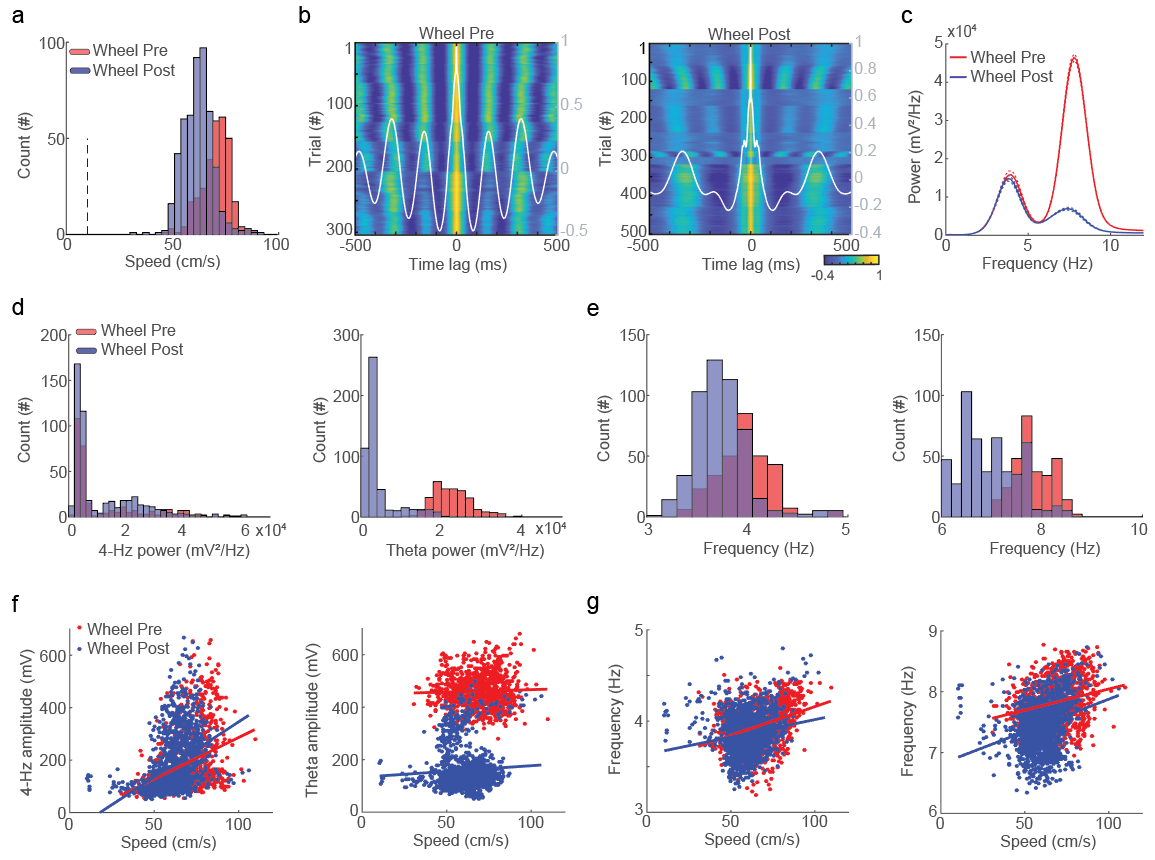

**Figure 3 - Hippocampal 4-Hz oscillations are resistant to pharmacological inactivation of the medial septum. (A) **Histograms of running speed at the wheel before (red, n=304 trials) and after (blue, n=501 trials) muscimol inactivation of the medial septum. **(B) **Color-coded autocorrelograms of LFP signals across runs at the wheel before (left) and after (right) muscimol. Gray traces represent the average autocorrelograms.** (C) **Average power spectra at 0-12 Hz during wheel runs. Solid lines represent the mean and dashed lines represent ± SEM. **(D)** Histograms of 4-Hz band power (left) and theta band power (right) before and after muscimol. **(E)** Histograms of 4-Hz band peak frequency (left) and theta band peak frequency (right) before and after muscimol.** (F) **Scatter plots of running speed and the instantaneous amplitude of 4-Hz (left) and theta (right) oscillations before and after muscimol. **(G) **Scatter plots of running speed and the instantaneous frequency of 4-Hz (left) and theta (right) oscillations before and after muscimol.

% fig 3
fig = figure(3);clf
fig.Position = [0,0, 1600, 500];
% Panel A
subplot(3,4,1)

% Panel B
% b1
subplot(3,4,2)

% b2
subplot(3,4,3)

% Panel C
% c1
subplot(3,4,4)
% c2
subplot(3,4,5)
% Panel D
subplot(3,4,6)
% Panel E
% e1
subplot(3,4,7)
% e2
subplot(3,4,8)
% Panel F
% f1
subplot(3,4,9)
% f2
subplot(3,4,10)

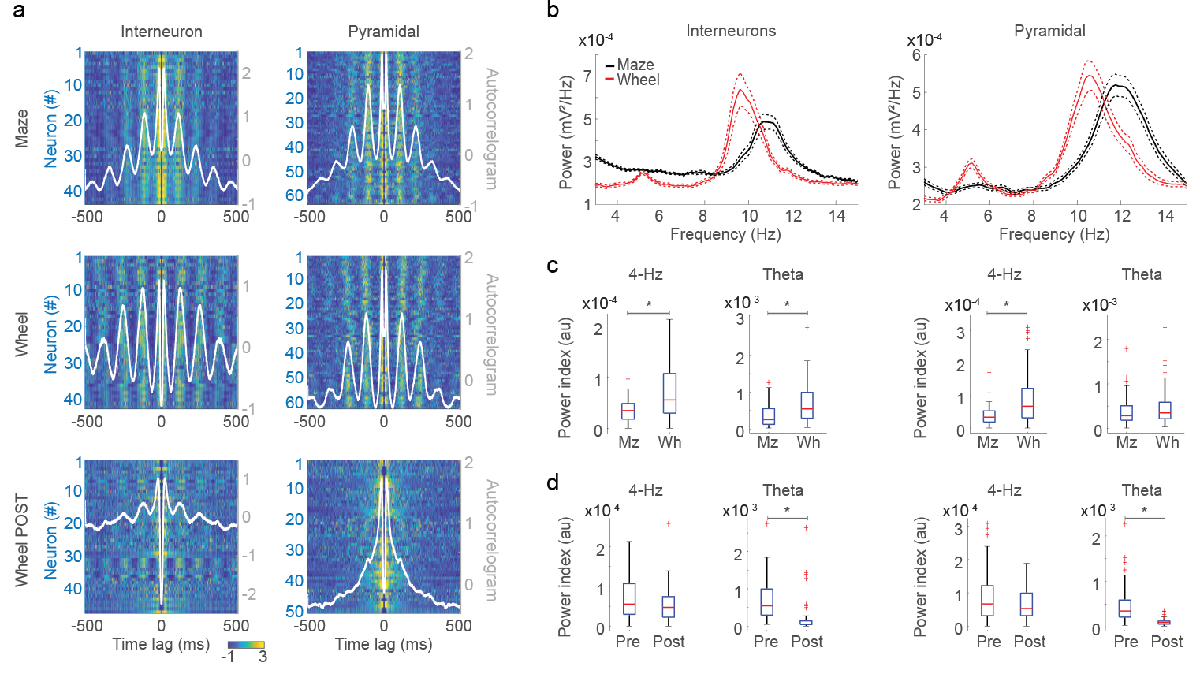

**Figure 4 - Spiking activity exhibits 4-Hz oscillations. **Maze versus wheel running: Interneurons at 4 Hz p < 0.01; Interneurons at theta p < 0.01; Pyramidal at 4 Hz p <= 0.01; Pyramidal at theta p = 0.20708; Pre versus post-muscimol during wheel running: Interneurons at 4 Hz p = 0.13903; Interneurons at theta p <= 0.01; Pyramidal at 4 Hz p = 0.24289; Pyramidal at theta p <= 0.01; 

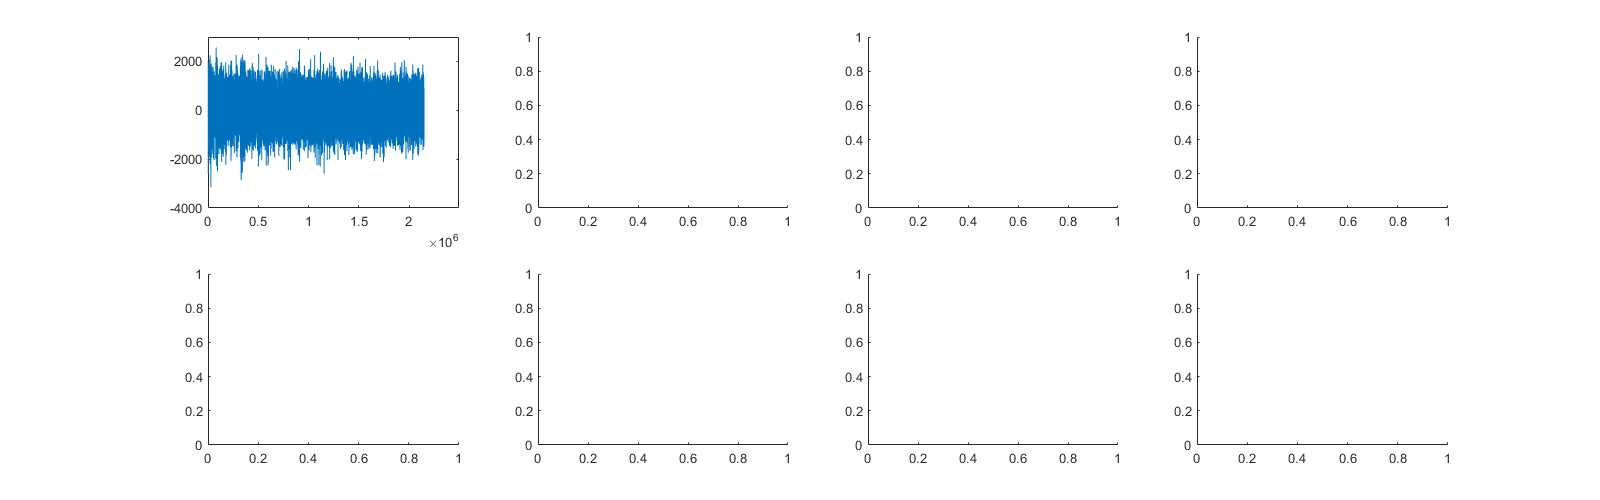

% Fig 4
fig = figure(4);clf
fig.Position = [0,0, 1600, 500];

% Panel A
subplot(3,8,1)

% Panel B
% b1
subplot(3,8,2)

% b2
subplot(3,8,3)

% Panel C
% c1
subplot(3,8,4)
% c2
subplot(3,8,5)
% Panel D
subplot(3,8,6)
% Panel E
% e1
subplot(3,8,7)
% e2
subplot(3,8,8)
% Panel F
% f1
subplot(3,8,9)
% f2
subplot(3,8,10)

## Supplemental Information